
ex1 = 'example1.dat'

ex1 = 'example1.dat'

ex2 = 'example1.dat'

ex2 = 'example1.dat'



E = csvread('example2.dat')

E =      2     1     1
     9     1     1
    12     1     1
    18     1     1
    20     1     1
    21     1     1
    24     1     1
    26     1     1
    31     1     1
    36     1     1



% Algo

%1, Form A with A_ij = exp(-abs(s_i-s_s)^2/2sig^2) if i!=j and A_ii = 0
%2, definde D diagnonal matrix with (i,i) element sum of A's iith row and L
%2b, L = D^(-1/2)AD^(1/2)
%3 find X with k eignvectors form L and for X
%4 For the matrix Y from X by renomalizing Xs ros to have unit len
%5 TReat every row in Y as a point in R^k and use K clusters with K-means
% assign the orignal point s_i to cluster j if and only if Y is asigned toj

k = 2

k = 2

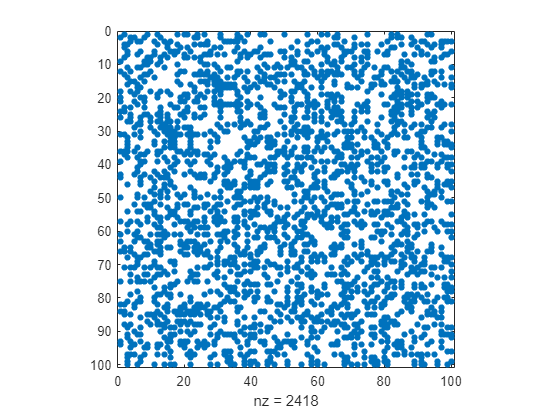


% 1 from canvas
col1 = E(:,1);
col2 = E(:,2);

max_ids = max(max(col1,col2));
As= sparse(col1, col2, 1, max_ids, max_ids); 
A = full(As);

spy(A)


A

A =      0     1     0     0     0     0     0     0     1     0     0     1     0     0     0     0     0     1     0     1     1     0     0     1     0     1     0     0     0     0     1     0     0     0     0     1     0     0     1     0     0     0     1     1     0     0     0     0     0     1
     1     0     0     1     1     0     0     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     1     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     1     1     0     0     0     1     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     1     1     1     1     0     1     0     0     0     0     0     0     0     1     0     0     0     0
     0     1     1     0     0     0     0     0     0     0     0     1     0     0     1   

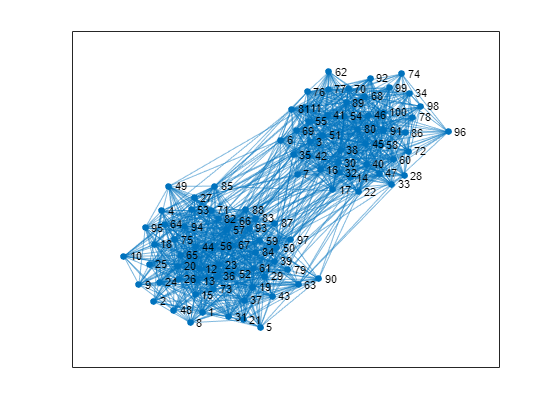


plot(graph(A));


%2
D=diag(sum(A,2));

L=(D^(-1/2)*A*D^(-1/2));

%3
[V,D] = eigs(L,k); %A

%4
Y= V./sum(V.*V,2).^(1/2);

%5
clust = kmeans(Y,k)

clust =      2
     2
     1
     2
     2
     1
     1
     2
     2
     2


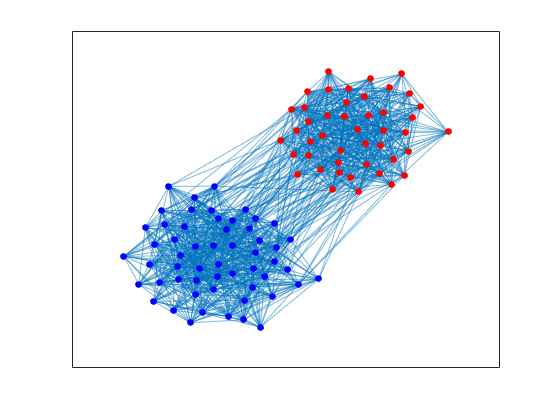



c = ["r" "b" "g" "y"];

h = plot(graph(A),"NodeLabel",{});

for i=1:k
    highlight(h, find(clust==i) , 'NodeColor', c(i))
end

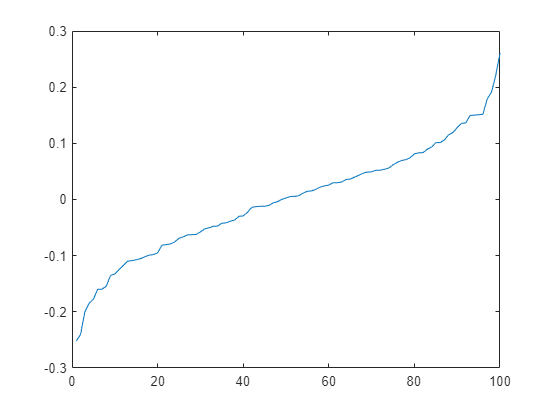


[FielderV,~]=eigs(L,2,'SA');
ordered = sort(FielderV(:,2));


plot(ordered)